clear; close all; clc;tic;

Num_bits = 10^6;
Data = randn(1,Num_bits) > 0.5;
SNR_Resolution = 0.1;
SNR=0:SNR_Resolution:10;

% Hamming Encoder
Coded_Data = Hamming_7_4_Encoder(Data);

% BPSK Modulations
BPSK_Not_Coded = 2*Data-1;
BPSK_Mod_Data = 2*Coded_Data-1;

% BER vectors
coded_BER = zeros(1,length(SNR));
Not_coded_BER = zeros(1,length(SNR));

for i=1:length(SNR)
    fprintf("\b\b\b\b\b\b\b\b%%%.2f", (i-1)*10*SNR_Resolution);
    % AWGN 
    AWGN_Data = awgn(complex(BPSK_Mod_Data),SNR(i),"measured");
    AWGN_Data_not_Codded = awgn(complex(BPSK_Not_Coded),SNR(i),"measured");
    
    % BPSK Demodulation
    BPSK_Demod_Data = real(AWGN_Data) > 0;
    BPSK_Demod_not_Codded_Data = real(AWGN_Data_not_Codded) > 0;
    
    % BPSK_Demod_Data = real(BPSK_Mod_Data) > 0;
    % BPSK_Demod_not_Codded_Data = real(BPSK_Not_Coded) > 0;

    % Hamming Decoder
    Decoded_Data = Hamming_7_4_Decoder(BPSK_Demod_Data);

    % BER calculation
    coded_BER(i) = sum(Data~=Decoded_Data)/Num_bits;
    Not_coded_BER(i) = sum(Data~=BPSK_Demod_not_Codded_Data)/Num_bits;
end

%100.00


% BER Graph
fprintf("\b\b\b\b\bResult:");

Result:

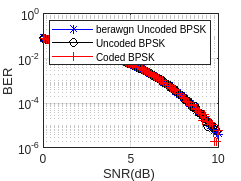


uncoded_BER = berawgn(SNR, "psk", 2, "nondiff");

semilogy(SNR, uncoded_BER, 'b*-','linewidth',1);grid on; hold on;
semilogy(SNR, Not_coded_BER, 'ko-','linewidth',1);grid on; hold on;
semilogy(SNR, coded_BER, 'r+-','linewidth',1); grid on;
xlabel('SNR(dB) '); ylabel('BER'); legend('berawgn Uncoded BPSK', 'Uncoded BPSK','Coded BPSK');


toc;

Elapsed time is 942.009574 seconds.
